Lab 2 Jeff Jiang 

Problem 1

In lecture and homework we explored how the convolution can be used to calculate the probability of a sum or average. For this problem we are going to imagine that we are looking for gamma-ray sources (e.g. with the [Fermi telescope](https://fermi.gsfc.nasa.gov)). In this kind of telescope there is a background of cosmic-rays (electrons and protons, mostly) that provides a discrete noise term across the sky that precisely follows a Poisson distribution. To detect a gamma-ray source, you need to ask what is the probability that the cosmic-ray background would have given you a measurement as signal-like or more than the signal that you received.

To set up the problem, assume in 1 day the average cosmic-ray background is some number X (pick someting btwn 0.5 and 10, with different values for you and your lab partner); and the average number of gamma-rays emitted by your hypothetical source is Y (pick something larger than X).

A) Show how the probability distribution of the background changes as you integrate (sum) for more days.

As the sum of the day increase, the pdf distribution of the background become more symmetric. The mean of the pdf distribution shift to the right. The hight of pdf distribution decreases because the distribution spreads out more as day increase.

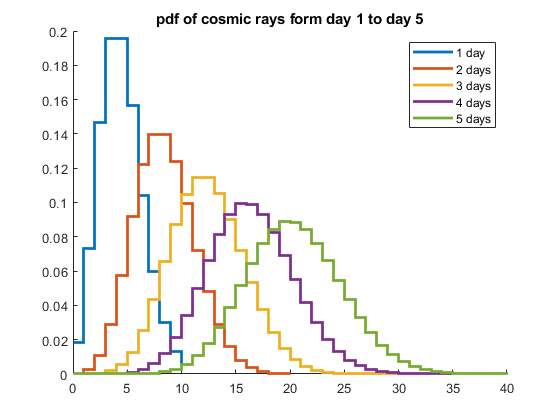

clear all;close all;clc;
cosmic = 4;
gamma = 6;

x1 = 0:10;
p1 = poisspdf(x1,cosmic);
o1 = p1;
figure
hold on
stairs(x1,p1,"LineWidth",2);
title('pdf of cosmic rays form day 1 to day 5');
xlim([0 40])
for i = 1:4
    p2 = conv(o1,p1);
    x2 = 0:10*(i+1);
    stairs(x2,p2,"LineWidth",2);
    o1 = p2;
end
legend('1 day','2 days','3 days','4 days','5 days')
hold off

B) Show that after 5 days, the summed probability distribution is still a Poisson distribution. Explain why this makes sense from a mathematical and conceptual point of view.

After 5 days and the summed probability distribution is similar with poisson pdf of 5 times the cosimc as show below. 

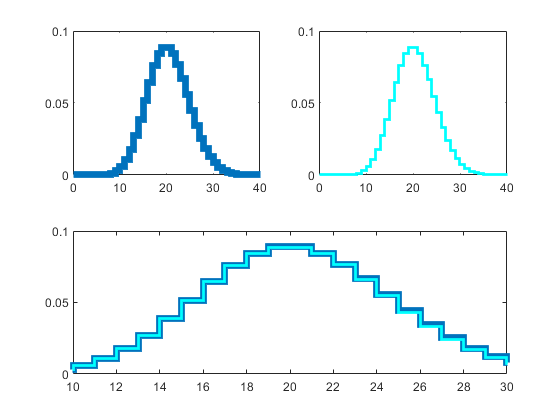

p3 = poisspdf(x2,cosmic*5);
figure
subplot(2,2,1);

stairs(x2,p3,"LineWidth",5);
xlim([0 40]);
subplot(2,2,2);
stairs(x2,p2,"LineWidth",2,"Color",'cyan');
xlim([0 40]);
subplot(2,2,[3,4]);
stairs(x2,p3,"LineWidth",5);
hold on
stairs(x2,p2,"LineWidth",2,"Color",'cyan');
xlim([10 30]);
hold off

C) Show how the probability distribution evolves as you *average* days. Calculate for many different ranges of days, and explore the shape of the distribution as the number of days becomes larger. Discuss this in relation to both B) and the central limit theoem.

As the days increase and take the average of the x-axes the distribution becomes narrower. The mean stady the same. The central limit Theorem states that the sampling distribution of the sample means approaches a normal distribution as the sample size gets larger. As graph show on the day 5 the curve of pdf is more like a gaussian distribution

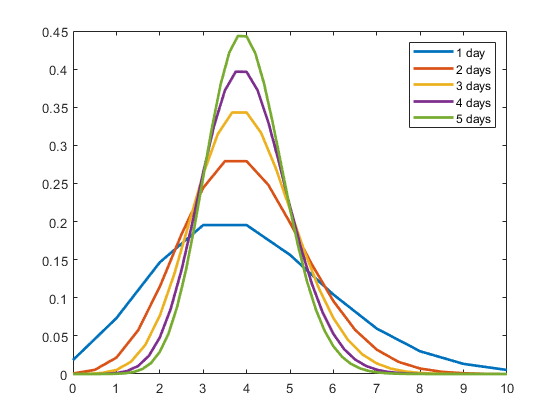

figure
o2=p1;
nx1 = x1 / 1;
np1 = p1 * 1;
plot(nx1,np1,"LineWidth",2);
hold on
for i = 1:4
    p3 = conv(o2,p1);
    x3 = 0:10*(i+1);
    nx2 = x3 / (i+1);
    np2 = p3 * (i+1);
    plot(nx2,np2,"LineWidth",2);
    o2 = p3;
end
legend('1 day','2 days','3 days','4 days','5 days')
hold off

D) Pick some number of days N, and assume you saw Y*N gamma rays from your source. Calculate the 'sigma' of your observation. [In reality the number of gamma-rays seen from a source will also fluctuate, but we're going to ignore that complication for a couple of labs.]

I picked day 1 for this part. 

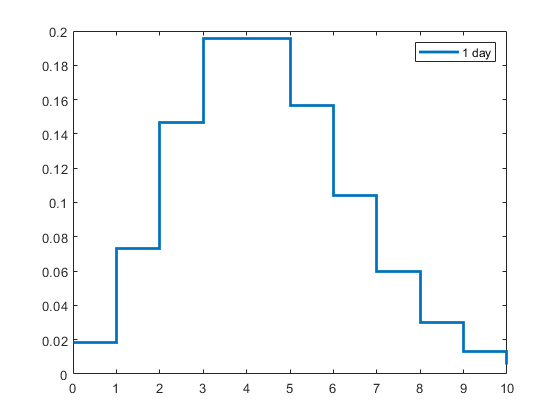

stairs(x1,p1,"LineWidth",2)
legend('1 day')

pd1 = makedist("Poisson","lambda",cosmic);
probability3 = cdf(pd1,gamma);
disp("The probability to find 6 gamma is "+ probability3);

The probability to find 6 gamma is 0.88933


sigma4 = norminv(probability3);
disp("The sigma for the probability is "+ sigma4);

The sigma for the probability is 1.223


Problem 2

Pick a skewed continuous distribtuion, such as a Rayleigh, that describes your background over some observing interval.

A) Show how the distribution changes as you average over more observing intervals.

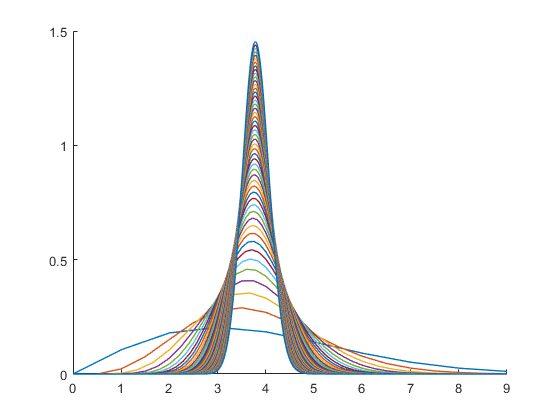

Rx1 = 0:1000;
Rp1 = raylpdf(Rx1,3);
Rp1 = Rp1/sum(Rp1);
Ro1 = Rp1;
figure
hold on
plot(Rx1,Rp1,"LineWidth",1);
for i = 2:50
    Rp2 = conv(Ro1,Rp1);
    Rx2 = 0:1000*i;
    plot(Rx2/i,Rp2*i,"LineWidth",1);
    Ro1 = Rp2;
end
xlim([0 9])
hold off

B) Discuss how the shape changes. Does it approach a Gaussian distribution? If yes, after how many intervals?

testx = (0:length(Rp2)-1)/i

testx = 	1.0e+03 *

         0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010


testm = sum(testx.*Rp2)

testm = 3.7953

testv = sqrt(sum((testx - testm).^2.*Rp2))

testv = 0.2744

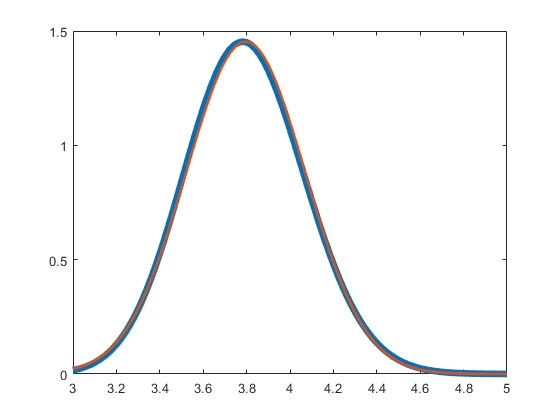

testy = normpdf(testx,testm,testv);
plot(testx,Rp2*i,"LineWidth",5);
hold on;
plot(testx,testy,"LineWidth",2);
xlim([3 5]);
hold off;

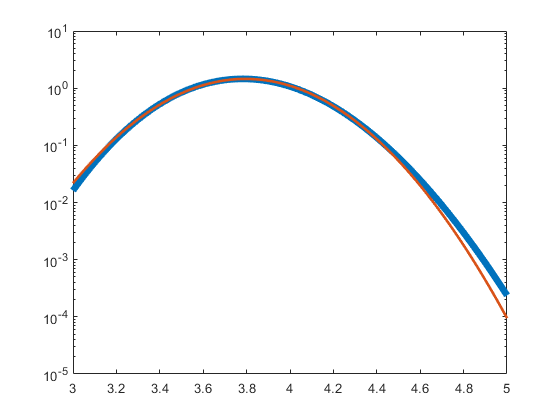

plot(testx,Rp2*i,"LineWidth",5);
hold on;
plot(testx,testy,"LineWidth",2);
xlim([3 5]);
set(gca,'YScale','log');

I graphed a Gaussian distribution with the same mean and standard deviation taken form the . The shape become less skewed to the left as more convolution are done. It does approach a look of Gaussian distribution after many convolution. But form the log graph it is still off.

Problem 3

The discovery of optical/infra-red counterparts of Neutron star mergers initially detected with gravity-waves is one of the great discoverys in the last few years ([wikipedia](https://en.wikipedia.org/wiki/GW170817), [scientific paper](https://arxiv.org/abs/1710.05833)), and has ushered in the age of "multi-messenger astrophysics." The science that can be done by matching a gravity-wave signal (directly measures the mass of the neutron stars and their distance) with the optical emisson (redshift, nuclear astrophysics of the resulting explosion) is *staggering*. Lots of science from how the heaviest elements are formed to constraints on Dark Energy.

We're going to explore one of the analysis questions that comes up when looking for the optical counterparts (a new optical source) of a gravity wave signal. For this problem let's assume that we are using an optical telescope with a thermal noise background from the CCD (dark current, particularly an issue with older CCDs and/or infra-red CCDs). After flat-fielding, the background appears as a zero-mean Gaussian with constant width over the image.

Version 1

You have an alert from [LIGO](https://www.ligo.caltech.edu) that is also seen in with the X-ray/ultra-violet satellite [SWIFT](https://swift.gsfc.nasa.gov). SWIFT gives you a very precise location, so you take an image of that part of the sky. But because of SWIFT's accuracy, you know which pixel in your image to look for a counterpart in.

A) From looking at all the other pixels in your image, you can measure the width of the background Gaussian distribution X (pick something). Assuming you see a signal of strength Y (pick a floating-point number; optical CCDs are not sensitive enough to count photons so the readings are floating point brightnesses, not integer photons). Calculate the significance of your detection. Can you claim a discovery (traditionally 5-sigma or more)?

A) From looking at all the other pixels in your image, you can measure the width of the background Gaussian distribution X (pick something). Assuming you see a signal of strength Y (pick a floating-point number; optical CCDs are not sensitive enough to count photons so the readings are floating point brightnesses, not integer photons). Calculate the significance of your detection. Can you claim a discovery (traditionally 5-sigma or more)?

The Gaussian distribution I piked is Normal distribution with Mean (mu) 3 and Standard deviation (sigma) 1. The floating-point number I picked is 9.5.

The result I got for sigma is 6.5 which mean I can claim a discovery since is 5 sigma or more.

p3pd1 = normcdf(9.5,3,1,'upper');
disp("The probability to find 6.5 at normal distribution is "+ p3pd1);

The probability to find 6.5 at normal distribution is 4.016e-11


p3sigma1 = norminv(p3pd1);
disp("The sigma for the probability is "+ p3sigma1);

The sigma for the probability is -6.5


Version 2

You have an alert from LIGO, but no associated detection from SWIFT. This could be because it is a black hole-black hole merger, a black hole-neutron star merger (neither seem to emit X-rays or UV light), or it could because SWIFT was indisposed at the time (wrong side of the earth in its orbit). Whatever the cause, you know what region of the sky to look in, but not which pixel.

B) If you have to look for a signal in 10k pixels, what is the probability distribution of your background? (*Clearly* state the statistical question, then turn that into math using your background distribution from part 1 of this problem.)

Statistical Question: The background is a Gaussian Distribution, with a mean of 3. The stronger the signal the more events we expect. So what is the probablilty distribution of the background produsing a signal with greater than 9.5 events with signal in 10k pixels? 

p3pd2 = 10000*p3pd1;
disp("The probability to find 6.5 at normal distribution is "+ p3pd2);

The probability to find 6.5 at normal distribution is 4.016e-07


C) Taking your brightest candidate signal from the region (assume it has the same signal as in part 1), calculate the significance of your detection.

p3sigma2 = norminv(p3pd2);
disp("The sigma for the probability is "+ p3sigma2);

The sigma for the probability is -4.9346


Problem 4

The statistical issue we were exploring in the previous problem is called a trials factor (sometimes known as a look-elsewhere effect). This is an important effect, as if you search through a million locations, you would expect to se ~1 one in a million event. However, it is also often over estimated how big an impact this makes on the sensitivity of a search. So in this part of the lab we are going to invert the problem.

Let us again assume we have a Gaussian background (same parameters as Problem 3).

A) Calculate the signal required for a 5-sigma detection in Version 1

p4x1 = makedist("Normal","mu",3,"sigma",1);
p4sigma1 = normcdf(5,'upper')

p4sigma1 = 2.8665e-07

p4signal1 = icdf(p4x1,1-p4sigma1)

p4signal1 = 8.0000

B) Calculate the signal required for a 5-sigma detection in Version 2

p4signal2 = icdf(p4x1,1-p4sigma1/10000)

p4signal2 = 9.5505

C) Discuss how much brighter the signal must be for discoverey if you have a trials factor of 10k. Looking at your probability distributions, explain why the sensitivity penalty due to a trials factor is so low.

I think since this is a guassian distribution, the senstive pentaly due to a lot of trails is low, because when you have more trials the probability falls off more quickly. 

D) If you changed the trials factor significantly (orders of magnitude), how large is the effect on your 5-sigma sensitivity threshold?

In a gaussian distribution if you change the trials factor significanly, the effect on you 5-sigma sensitivity threshold should change less and less significant. 

Extra credit: If you had a different distribution shape (non-Gaussian), how would that affect the sensitivity penalty of many trials? Clearly explain.

If we have different distribution we can try to find most influential input to see the inpact on the distribution falls. Higher the sensitivity penalty falls off more quicly. 